# **Estimation of signal parameters from noisy observations**

## Introduction

Computation of MSE requires three parameters:

- signal-to-noise ratio

- dominant frequency of the signal

- length of the a priori interval

This script explains how to determine these parameters

This script reproduces Figures 5 and 6 published in the paper:

Abakumov, I., Roeser, A., and S. A. Shapiro (2020) The arrival time picking uncertainty: theoretical estimationsand their application to microseismic data, Geophysics

**Authors**: I. Abakumov, A. Roeser, S.A. Shapiro

**Publication date**: 20th of February 2020

**E-mail**: abakumov_ivan@mail.ru

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Design low-pass & bandpass filter

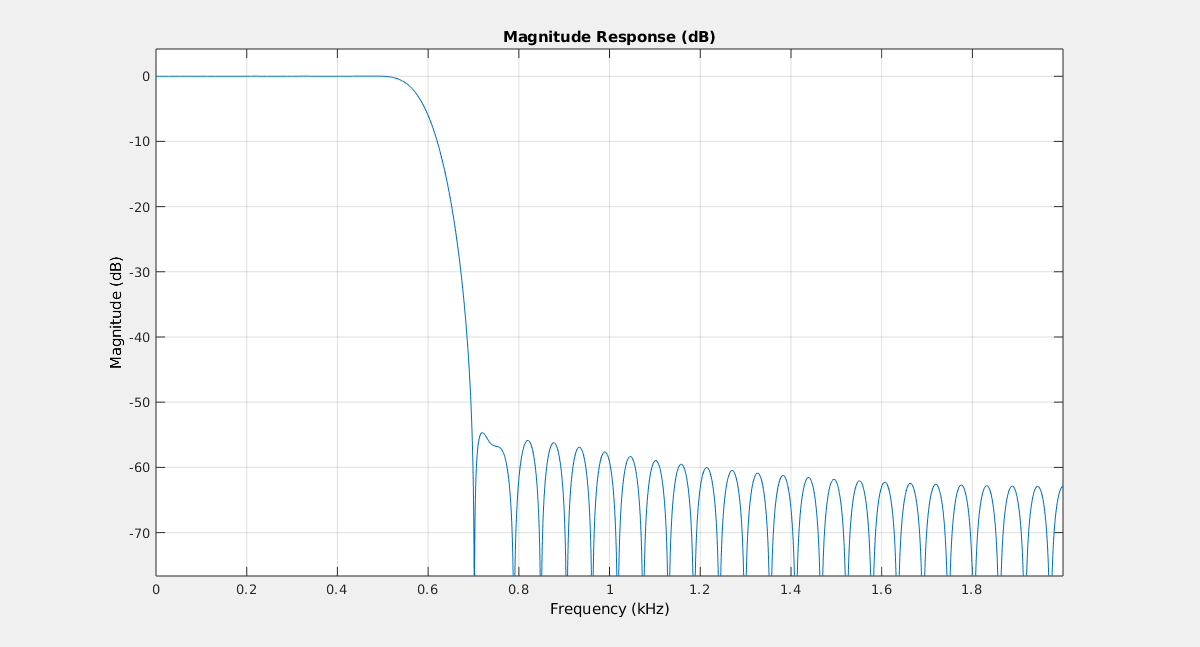

lpFilt = designfilt('lowpassfir','FilterOrder',70, ...
    'CutoffFrequency',600,'SampleRate',4000);
fvtool(lpFilt)

## Load event file

Event = MLD([mlibfolder '/Examples/Arrival_time_uncertainty/Data/Event_example.mat']);

## Definition of basic values

Fs = 4000;              % sampling frequency
dt = 1/Fs;              % time step 
t0 = 0; 
tt = t0:dt:1.5-dt;
nt = length(tt);

## Acquisition

acq.sx = Event.SensorEasting;
acq.sy = Event.SensorNorthing;
acq.sz = Event.SensorDepth;
nsta = length(acq.sx);

## Upload arrival times of P- and S-waves

P- and S-wave arrival time (in seconds)

Tp = Event.PTime;
Ts = Event.STime;
Ts(end) = Ts(end-1);

## Create SNR

fig =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 919
        Name: ''
       Color: [1 1 1]
    Position: [100 100 600 800]
       Units: 'pixels'

  Show all properties


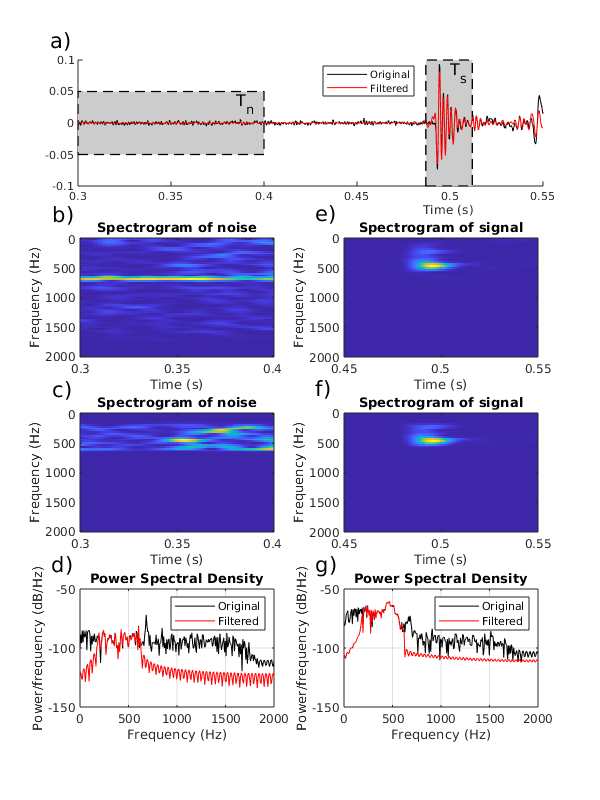

W = zeros(1,31); 
N0 = zeros(1,31);
Beta = zeros(1,31);
Td = 1/400; 

for i = 2:31
    
    trace = Event.tracesx(:,i);
    traceft = bandpass(trace,[200 600],Fs);
    
    tnmin = x2grid(0.3, t0, dt, nt); 
    tnmax = x2grid(0.4, t0, dt, nt); 

    tsmin = x2grid(0.45, t0, dt, nt); 
    tsmax = x2grid(0.55, t0, dt, nt);
    
    tdmin = x2grid(Tp(i), t0, dt, nt); 
    tdmax = x2grid(Tp(i)+2*Td, t0, dt, nt);
        
    indn = tnmin:tnmax; 
    inds = tsmin:tsmax; 
    indd = tdmin:tdmax; 

    
    signal   = trace(inds);
    noise    = trace(indn);
    dsignal   = trace(indd);

    signalft = traceft(inds);
    noiseft  = traceft(indn);
    dsignalft   = traceft(indd);

    N0(i) = var(noiseft)*dt;
    W(i)  = sum(dsignalft.^2)*dt;
    Beta(i) = get_spectral_variance(dsignalft,dt);
    
    if i==3
    
        %--------------------------------------------
        fig = figure(919)
        set(fig, 'Position', [100 100 600 800])
        %fig.Color = [240/255 240/255 240/255];
        %fig.InvertHardcopy = 'off'; 

        
        subplot(4,2,[1 2])
        rectangle('Position',[0.3,-0.05,0.1,0.1], ...
            'FaceColor',[0.8 0.8 0.8],...
            'EdgeColor','k',...
            'LineWidth',1,'LineStyle','--')
        hold on
         rectangle('Position',[Tp(i)-0.005,-0.1,10*Td,0.2], ...
            'FaceColor',[0.8 0.8 0.8],...
            'EdgeColor','k',...
            'LineWidth',1,'LineStyle','--')
        hold on 
        p1 = plot(tt, trace,'k');
        hold on 
        p2 = plot(tt, traceft,'r');
        axis([0.3 0.55 -0.1 0.1])
        text(0.285, 0.13, 'a)', 'FontSize',16, 'Color','k')
        text(0.385, 0.03, 'T_n', 'FontSize',12, 'Color','k')
        text(0.5, 0.08, 'T_s', 'FontSize',12, 'Color','k')
        legend([p1 p2], 'Original','Filtered', 'Location','best')
        xlabel('Time (s)','Position',[0.499 -0.125])  
        
        subplot(4,2,3)
        [Snoise,F,~] = spectrogram(noise,100,98,128,Fs);
        imagesc(tt(indn),F,((abs(Snoise.^2))))
        xlabel('Time (s)')
        ylabel('Frequency (Hz)')
        title('Spectrogram of noise')
        text(0.285, -400, 'b)', 'FontSize',16, 'Color','k')
    
        subplot(4,2,5)
        [Snoise,F,~] = spectrogram(noiseft,100,98,128,Fs);
        imagesc(tt(indn),F,((abs(Snoise.^2))))
        xlabel('Time (s)')
        ylabel('Frequency (Hz)')
        title('Spectrogram of noise')
        text(0.285, -400, 'c)', 'FontSize',16, 'Color','k')
    
        subplot(4,2,4)
        [Ssignal,F,~] = spectrogram(signal,100,98,128,Fs);
        imagesc(tt(inds),F,((abs(Ssignal.^2))))
        axis([0.45,0.55,0, 2000])
        xlabel('Time (s)')
        ylabel('Frequency (Hz)')
        text(0.435, -400, 'e)', 'FontSize',16, 'Color','k')
        title('Spectrogram of signal')
    
        subplot(4,2,6)
        [Ssignal,F,~] = spectrogram(signalft,100,98,128,Fs);
        imagesc(tt(inds),F,((abs(Ssignal.^2))))
        axis([0.45,0.55,0, 2000])
        xlabel('Time (s)')
        ylabel('Frequency (Hz)')  
        text(0.435, -400, 'f)', 'FontSize',16, 'Color','k')
        title('Spectrogram of signal')
        
        subplot(4,2,7)
        [f,PSDn] = get_doublesided_PSD(noise,Fs);
        plot(f,SME(10*log10(PSDn),0),'k')
        hold on
        [f,PSDnft] = get_doublesided_PSD(noiseft,Fs);
        plot(f,SME(10*log10(PSDnft),0), 'r')
        title('Power Spectral Density')
        xlabel('Frequency (Hz)')
        ylabel('Power/frequency (dB/Hz)')
        legend('Original','Filtered')
        axis([0 Fs/2 -150 -50])
        grid on
        text(-300, -30, 'd)', 'FontSize',16)
        
    
        subplot(4,2,8)
        [f,PSDs] = get_doublesided_PSD(signal,Fs);
        plot(f,SME(10*log10(PSDs),0),'k')
        hold on
        [f,PSDsft] = get_doublesided_PSD(signalft,Fs);
        plot(f,SME(10*log10(PSDsft),0), 'r')
        title('Power Spectral Density')
        xlabel('Frequency (Hz)')
        ylabel('Power/frequency (dB/Hz)')
        legend('Original','Filtered')
        axis([0 Fs/2 -150 -50])
        grid on
        text(-300, -30, 'g)', 'FontSize',16)
        
    %--------------------------------------------
    end
end    


W = W-N0*length(indd);
N0_AWGN = N0*2000/400;

SNR = W./N0_AWGN;
SNRdb = 10*log10(SNR);
beta = mean(Beta(2:30));
MSE = get_SZZB(SNR,Td,Td);
err = sqrt(MSE)*1.96; % in ms, + 95% confidence interval
err(1) = 0;

## Plot results

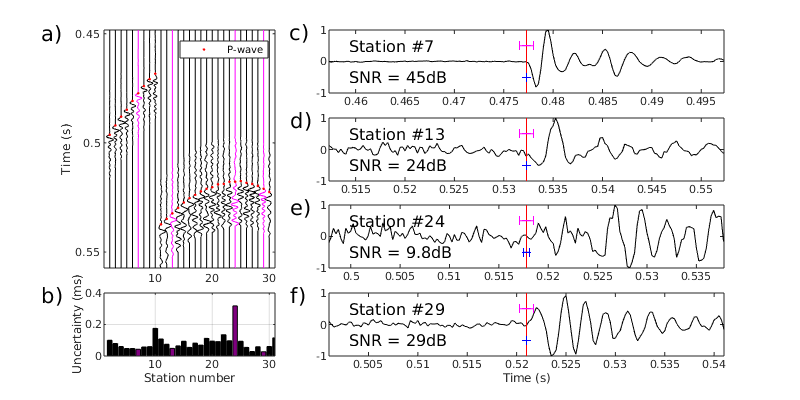

fig = figure(87);
set(fig, 'Position', [100 100 800 400])
%fig.Color = [240/255 240/255 240/255];
%fig.InvertHardcopy = 'off'; 

[Tx, Txft] = deal(zeros(6000,31));
[Tcut1, Tcut2] = deal(zeros(1,31));

for i = 1:31  
    
    Tcut1(i) =  Tp(i)-0.02;
    Tcut2(i) =  Tp(i)+0.02;
    
    tmin = x2grid(Tcut1(i), t0, dt, nt); 
    tmax = x2grid(Tcut2(i), t0, dt, nt);
        
    ind = tmin:tmax;
    
    Tx(ind,i) = Event.tracesx(ind,i);
end

set(fig, 'Position', [100 100 800 400])

subplot(4,3,[1 4 7])
for i=2:30
    plot(i+SME(Tx(:,i),2)/max(abs(Tx(:,i))), tt,'black')
    hold on
end
for i= [7 13 24 29]
    plot(i+SME(Tx(:,i),2)/max(abs(Tx(:,i))), tt,'magenta')
    hold on
end

pp = plot(1:30, Tp(1:30), '.red');
legend(pp, 'P-wave');
axis([1 31 min(Tcut1(2:end)) max(Tcut2)])
set(gca,'YDir','reverse')
ylabel('Time (s)')
text(-10, 0.45, 'a)', 'FontSize',16)


subplot(4,3,[2 3])
i = 7; 
trace = Tx(:,i)/max(abs(Tx(:,i)));
traceft = bandpass(trace,[200 600],Fs);
plot(tt, trace,'black')
hold on 
%plot(tt, traceft,'red')
plot(linspace(Tp(i),Tp(i),100), linspace(-1,1,100), 'r')
axis([Tp(i)-0.02 Tp(i)+0.02 -1 1])
errorbar(Tp(i),-0.5,err(i),'both','blue')
errorbar(Tp(i),+0.5,3*dt,'both','m')
text(Tp(i)-0.018, 0.5, ['Station #' num2str(i)], 'FontSize',12)
text(Tp(i)-0.018, -0.5, ['SNR = ' num2str(SNRdb(i),2), 'dB'], 'FontSize',12)
text(Tp(i)-0.024, 0.9, 'c)', 'FontSize',16)

subplot(4,3,[5 6])
i = 13; 
trace = Tx(:,i)/max(abs(Tx(:,i)));
traceft = bandpass(trace,[200 600],Fs);
plot(tt, trace,'black')
hold on 
%plot(tt, traceft,'red')
plot(linspace(Tp(i),Tp(i),100), linspace(-1,1,100), 'r')
axis([Tp(i)-0.02 Tp(i)+0.02 -1 1])
errorbar(Tp(i),-0.5,err(i),'both','blue')
errorbar(Tp(i),+0.5,3*dt,'both','m')
text(Tp(i)-0.018, 0.5, ['Station #' num2str(i)], 'FontSize',12)
text(Tp(i)-0.018, -0.5, ['SNR = ' num2str(SNRdb(i),2), 'dB'], 'FontSize',12)
text(Tp(i)-0.024, 0.9, 'd)', 'FontSize',16)

subplot(4,3,[8 9])
i = 24; 
trace = Tx(:,i)/max(abs(Tx(:,i)));
traceft = bandpass(trace,[200 600],Fs);
plot(tt, trace,'black')
hold on 
%plot(tt, traceft,'red')
plot(linspace(Tp(i),Tp(i),100), linspace(-1,1,100), 'r')
axis([Tp(i)-0.02 Tp(i)+0.02 -1 1])
errorbar(Tp(i),-0.5,err(i),'both','blue')
errorbar(Tp(i),+0.5,3*dt,'both','m')
text(Tp(i)-0.018, 0.5, ['Station #' num2str(i)], 'FontSize',12)
text(Tp(i)-0.018, -0.5, ['SNR = ' num2str(SNRdb(i),2), 'dB'], 'FontSize',12)
text(Tp(i)-0.024, 0.9, 'e)', 'FontSize',16)

subplot(4,3,[11 12])
i = 29; 
trace = Tx(:,i)/max(abs(Tx(:,i)));
traceft = bandpass(trace,[200 600],Fs);
plot(tt, trace,'black')
hold on 
%plot(tt, traceft,'red')
plot(linspace(Tp(i),Tp(i),100), linspace(-1,1,100), 'r')
axis([Tp(i)-0.02 Tp(i)+0.02 -1 1])
errorbar(Tp(i),-0.5,err(i),'both','blue')
errorbar(Tp(i),+0.5,3*dt,'both','m')
xlabel('Time (s)')
text(Tp(i)-0.018, 0.5, ['Station #' num2str(i)], 'FontSize',12)
text(Tp(i)-0.018, -0.5, ['SNR = ' num2str(SNRdb(i),2), 'dB'], 'FontSize',12)
text(Tp(i)-0.024, 0.9, 'f)', 'FontSize',16)

subplot(4,3, 10)
nerr = err; 
nerr(1:10) = err(1:10)*10;
b = bar(nerr*1000, 'black');
b.FaceColor = 'flat';
b.CData(7,:) = [0.5 0 .5];
b.CData(13,:) = [0.5 0 .5];
b.CData(24,:) = [0.5 0 .5];
b.CData(29,:) = [0.5 0 .5];
grid on
axis([1 31 0 0.4])
ylabel('Uncertainty (ms)')
xlabel('Station number')
text(-10, 0.38, 'b)', 'FontSize',16)